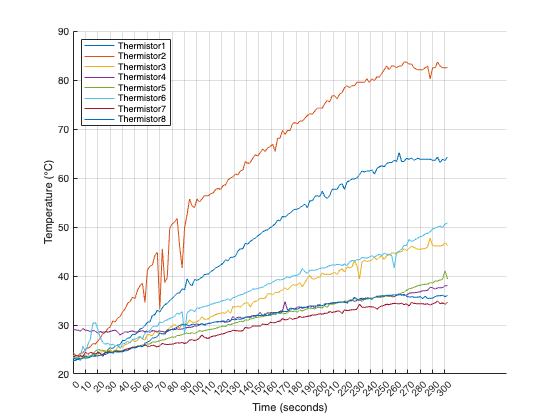

% Define the path to your CSV file
[fileName, filePath] = uigetfile('*.csv', 'Select the CSV file');
fullFilePath = fullfile(filePath, fileName);

% Read the CSV file into a table
data = readtable(fullFilePath);

% Ensure the timestamp column is read as text (string)
timestamps = string(data{:, 1});  % assuming the first column is the timestamp

% Convert the string timestamps to datetime and then calculate time in seconds
initialTime = datetime(timestamps(1), 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
timeInSeconds = seconds(datetime(timestamps, 'InputFormat', 'yyyy-MM-dd HH:mm:ss') - initialTime);

% Extract the thermistor and thermocouple data
thermistor1 = data.Thermistor1;
thermistor2 = data.Thermistor2;
thermistor3 = data.Thermistor3;
thermistor4 = data.Thermistor4;
thermistor5 = data.Thermistor5;
thermistor6 = data.Thermistor6;
thermistor7 = data.Thermistor7;
thermistor8 = data.Thermistor8;
% thermocouple = data.Thermocouple;

% Plot the thermistor and thermocouple data over time in seconds
figure;
hold on;
plot(timeInSeconds, thermistor1, 'DisplayName', 'Thermistor1');
plot(timeInSeconds, thermistor2, 'DisplayName', 'Thermistor2');
plot(timeInSeconds, thermistor3, 'DisplayName', 'Thermistor3');
plot(timeInSeconds, thermistor4, 'DisplayName', 'Thermistor4');
plot(timeInSeconds, thermistor5, 'DisplayName', 'Thermistor5');
plot(timeInSeconds, thermistor6, 'DisplayName', 'Thermistor6');
plot(timeInSeconds, thermistor7, 'DisplayName', 'Thermistor7');
plot(timeInSeconds, thermistor8, 'DisplayName', 'Thermistor8');
%plot(timeInSeconds, thermocouple, 'DisplayName', 'Thermocouple', 'LineWidth', 2);

% Customize the plot
xlabel('Time (seconds)');
ylabel('Temperature (°C)');

% Adjust the x-axis ticks to have more points
xticks(0:10:max(timeInSeconds));  % Increase the number of ticks every 10 seconds

% Move the legend to the top left
legend('Location', 'northwest');

% Show grid for better visibility
grid on;
hold off;